# Test mesh spectral

close all
clear variables
clc

## display properties

set(0, 'DefaultAxesFontname', 'Arial CE');
font_size = 16;
set(0, 'DefaultAxesFontsize', font_size);
set(0, 'defaulttextfontname', 'Arial CE');
set(0, 'defaulttextfontsize', font_size);
set(0, 'defaultfigurecolor', 'w');

## BODY

## set the 'nirfasterroot' as current folder

cd(nirfasterroot);

## load meshes

mesh_2d = load_mesh('circle2000_86_spec');

Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


mesh_3d = load_mesh('cylinder_spec');

Fixed sources
Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


disp('  *** meshes loaded')

  *** meshes loaded


## save meshes

save_mesh(mesh_2d,[nirfasterroot filesep 'test' filesep 'test_2d']);
save_mesh(mesh_3d,[nirfasterroot filesep 'test' filesep 'test_3d']);
disp('  *** meshes saved')

  *** meshes saved


## re-load meshes

mesh_2d = load_mesh([nirfasterroot filesep 'test' filesep 'test_2d']);

Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


mesh_3d = load_mesh([nirfasterroot filesep 'test' filesep 'test_3d']);

Fixed sources
Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


disp('  *** meshes re-loaded')

  *** meshes re-loaded


## plot meshes

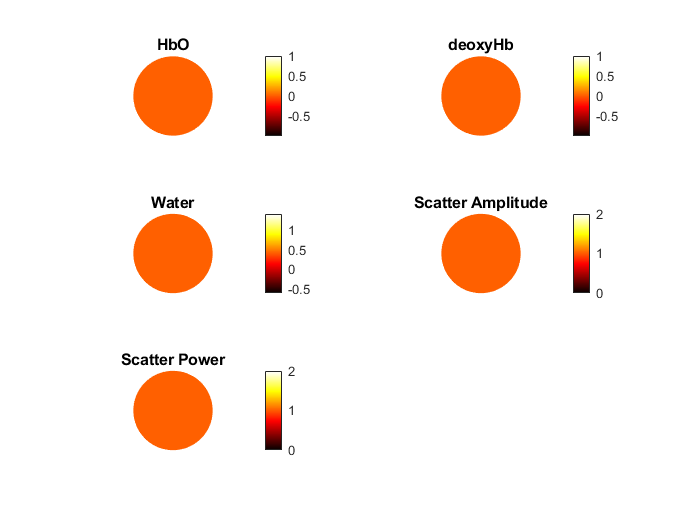

plotmesh(mesh_2d);

 
NOTICE: 3-D meshes are now only viewable using the NIRFASTSlicer or ParaView interfaces.
TO VIEW: Make sure the 3-D mesh is saved and has an associated .vtk file.
         Drag and drop the mesh's .vtk file into NIRFASTSlicer (as a Model).
         Use the Models module to adjust viewing parameters.


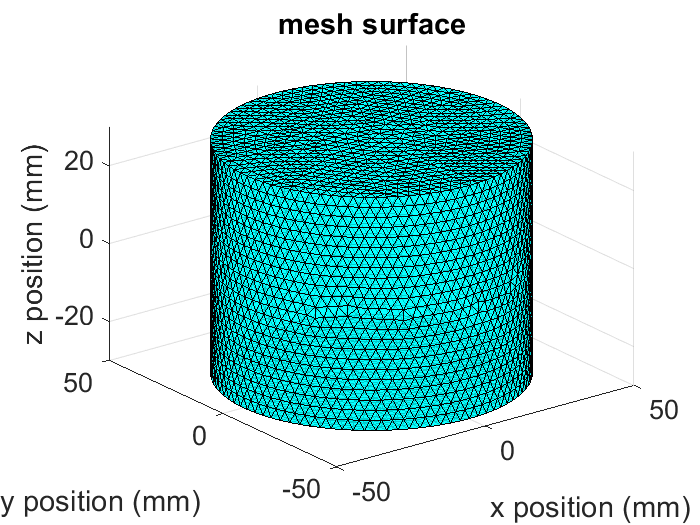

plotmesh(mesh_3d);

## plot meshes sources and detectors

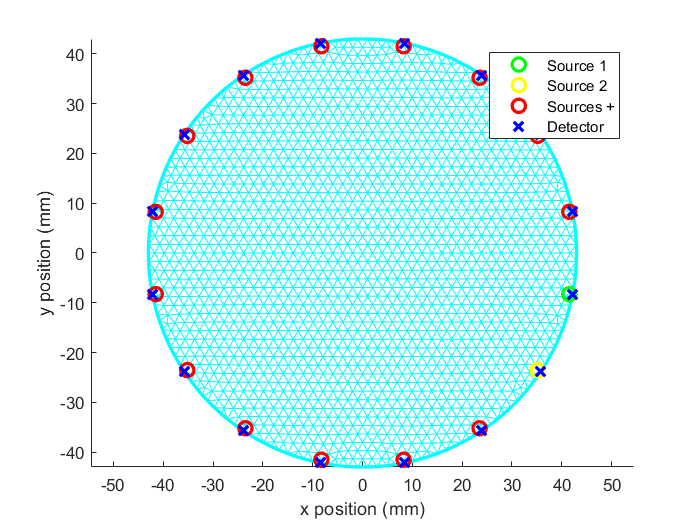

plotmesh_fiducials(mesh_2d);

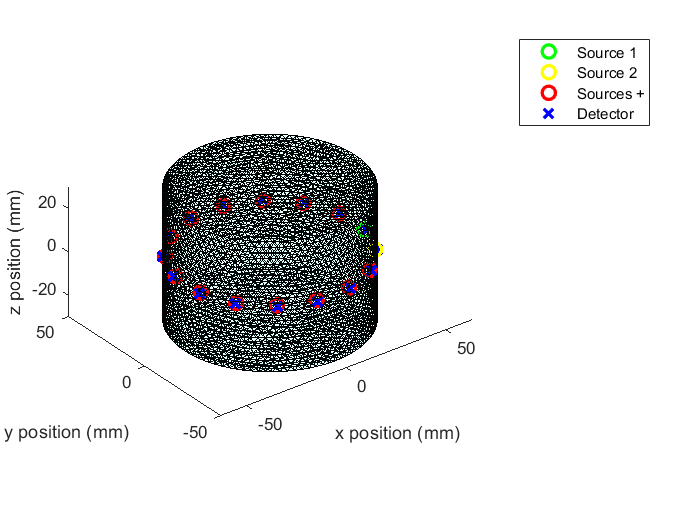

plotmesh_fiducials(mesh_3d);

## plot meshes statistics

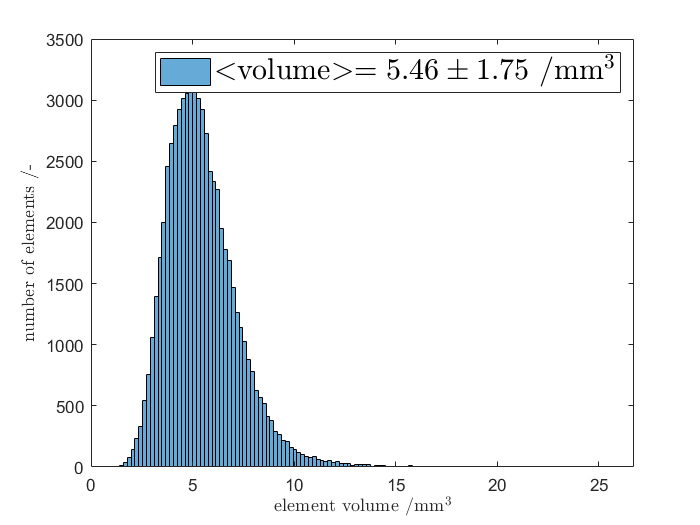

mesh_volume_distribution(mesh_3d)

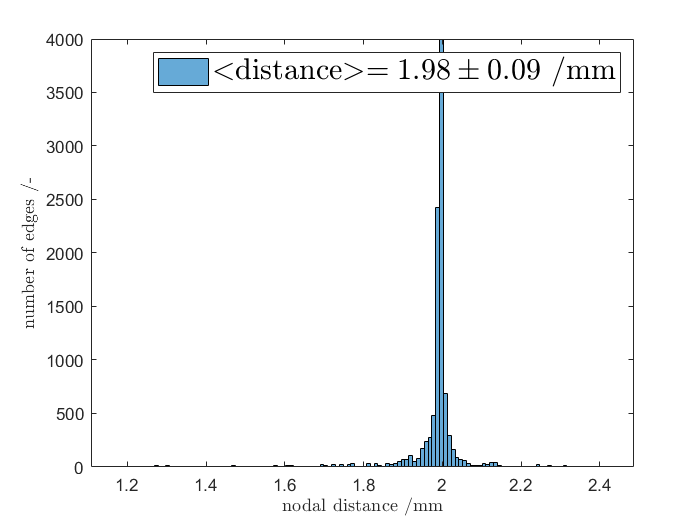


mesh_nodal_distance_distribution(mesh_2d)

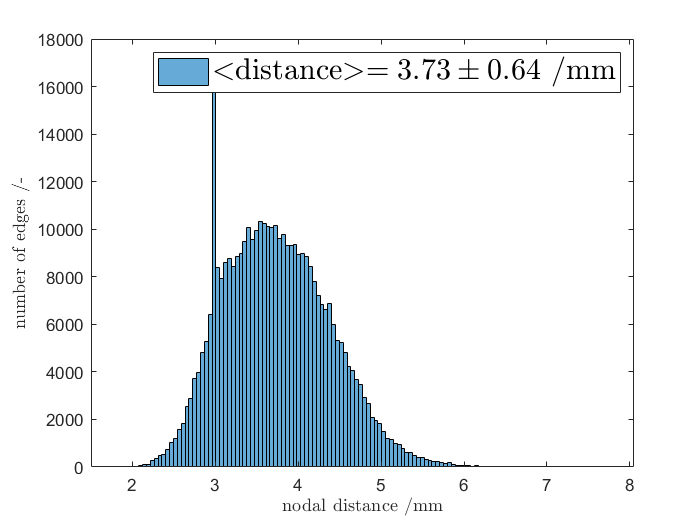

mesh_nodal_distance_distribution(mesh_3d)

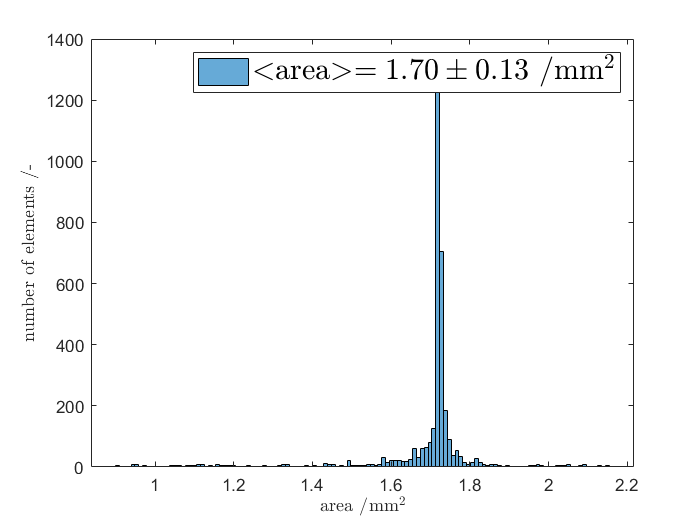


mesh_facets_area_distribution(mesh_2d)

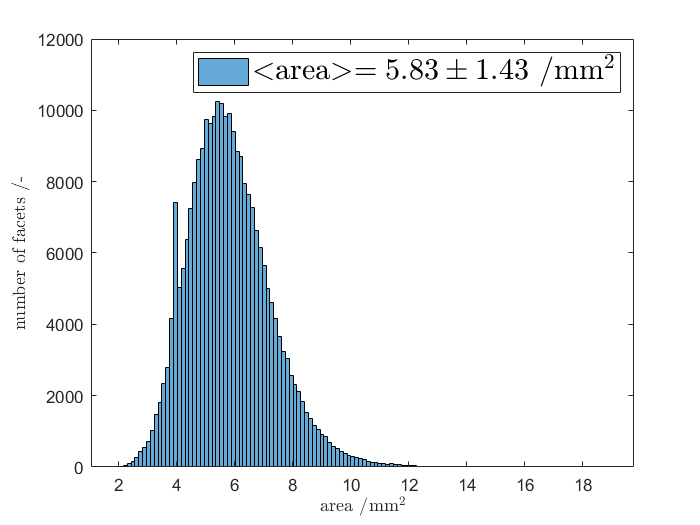

mesh_facets_area_distribution(mesh_3d)

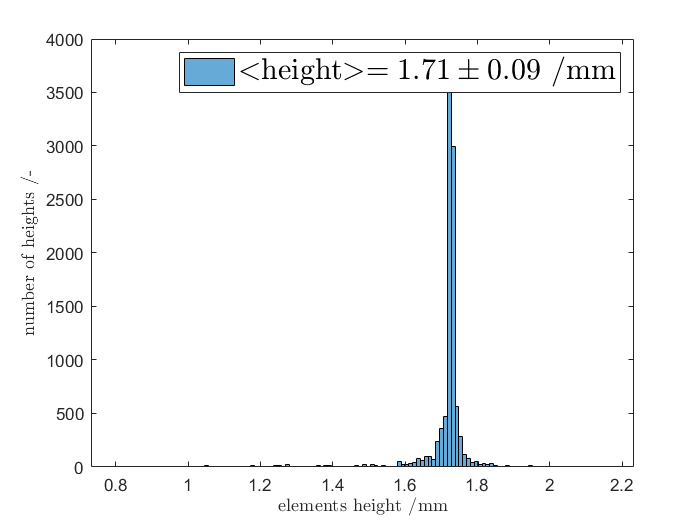


mesh_heights_distribution(mesh_2d)

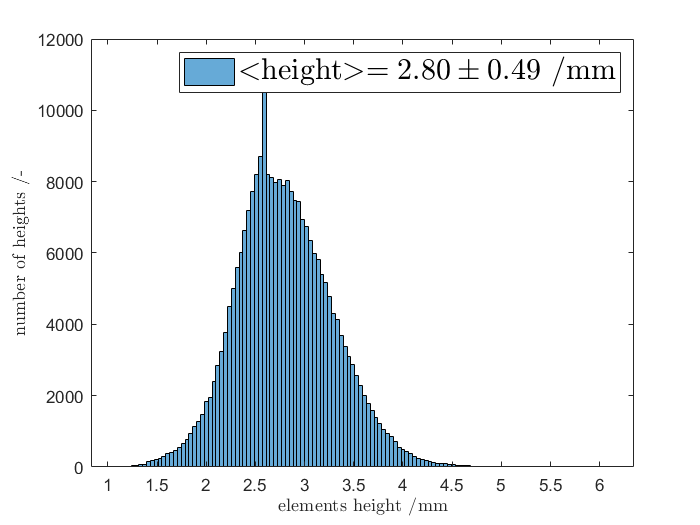

mesh_heights_distribution(mesh_3d)

## add a blob to the 2D meshes

blob.x = 0; % x position
blob.y = -10; % y position
blob.r = 10; % radius
% blob region number, max of current regions + 1
blob.region = max(unique(mesh_2d.region)) + 1;
blob.HbO = 0.020; % oxygenated haemolobin concentration im mM 
blob.deoxyHb = 0.015; % deoxygenated haemolobin concentration im mM
mesh_anomaly_2d = add_blob(mesh_2d,blob);

Number of nodes modified = 90


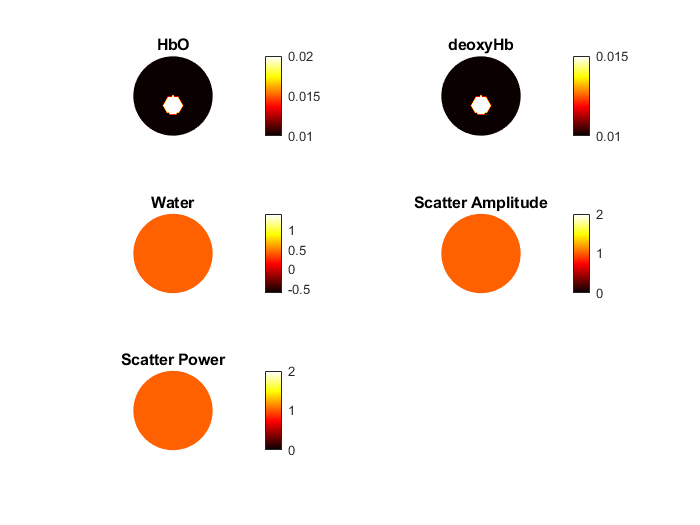

mesh_anomaly_2d.name = [mesh_anomaly_2d.name '_anomaly'];
plotmesh(mesh_anomaly_2d)